**Author: Marcin Mikuła**

**Real thermal system identification:**

The LiveScript consist of:

- Data preparation

- Choosing various model structures and estimating model parameters

- Usage of System Identification Toolbox

- Validation and comparision of the estimated models

## **1. Data preparation:**

% clc; clear;

%%%% PLC cycle time:
dt = 0.1; %% 100 ms

%%%%%%%%%%%% Import data from text files
data1 = readtable('25_percent_U.txt');

data2 = readtable('50_percent_U.txt');

data3 = readtable('100_percent_U.txt');

data4 = readtable("cooling_data.txt");




%%%%% y and u vectors
offset_Y1_Temp = data1.D20(1);
Y1 = data1.D20 - offset_Y1_Temp;
U1 = data1.D30./100;

offset_Y2_Temp = data2.D20(1);
Y2 = data2.D20 - offset_Y2_Temp;
U2 = data2.D30./100;

offset_Y3_Temp = data3.D20(1);
Y3 = data3.D20 - offset_Y3_Temp;
U3 = data3.D30./100;


Y4 = data4.FLOAT_DEC_7_;
offset_Y4_Temp = Y4(length(Y4));
Y4 = Y4 - offset_Y4_Temp;

U4 = data4.FLOAT_DEC_7__1./100;


%%%%%% index vector
index1 = data1.D15;
index2 = data2.D15;
index3 = data3.D15;
index4 = data4.INDEX;


%%%%%%%% time vectors
t1 = index1 * dt;
t2 = index2 * dt;
t3 = index3 * dt;
t4 = index4 * dt;

data_25 = iddata(Y1,U1,dt);
data_50 = iddata(Y2,U2,dt);
data_100 = iddata(Y3,U3,dt);
data_cooling = iddata(Y4,U4,dt);

%%%%%%%%%% Lightweight data set: 100x smaller data set suitable for DL
%%%%%%%%% Toolbox for faster computing
datasets = {data_25, data_50, data_100, data_cooling};
datasets_light = cell(1,4);  % tutaj zapiszesz wersje "light"

step = 10;   % przerzedzenie (co którą próbkę bierzemy)

for i = 1:numel(datasets)
    d = datasets{i};
    U = d.InputData;
    Y = d.OutputData;
    
    idx = 1:step:length(U);   % weź co 'step'-tą próbkę
    U_lw = U(idx,:);
    Y_lw = Y(idx,:);
    
    % nowy obiekt iddata z powiększonym okresem próbkowania
    d_lw = iddata(Y_lw, U_lw, dt*step);
    
    datasets_light{i} = d_lw;
end

% Rozpakowanie
data_25_light      = datasets_light{1};
data_50_light      = datasets_light{2};
data_100_light     = datasets_light{3};
data_cooling_light = datasets_light{4};


%%%%%%%%%%%% Plot the measured data
plot(data_25,data_50,data_100,data_cooling);
title('Step responses of the system')
xlabel('Time [s]');
ylabel('Temperature [°C]');
legend('25%','50%','100%', 'Cooling')

## **2. Model strucures:**

- transfer functions: -  1st order + time delay, 2nd order with time delay, 3rd order with time dela

- nlarx model with Wavelet network and nlarx model with Sigmoid network

- nlarx with statistic and ml toolbox 

- nlarx with deeplearning toolbox

- Wiener-Hammerstein nonlinear model

**2.1 Transfer function - 1st, 2nd, 3rd order tf with time delay**

it turns out that the estimated system accuracy is strongly related to a chosen estimation data. Although the fit to the estimation data set might be above 90%, it's the fit to the validation data ( 25%, 50%, 100% PWM duty cycle, cooling) that really matters. The fit tends to be below 30%.

 It's clear that the transfer function might not be the appropriate model structure;

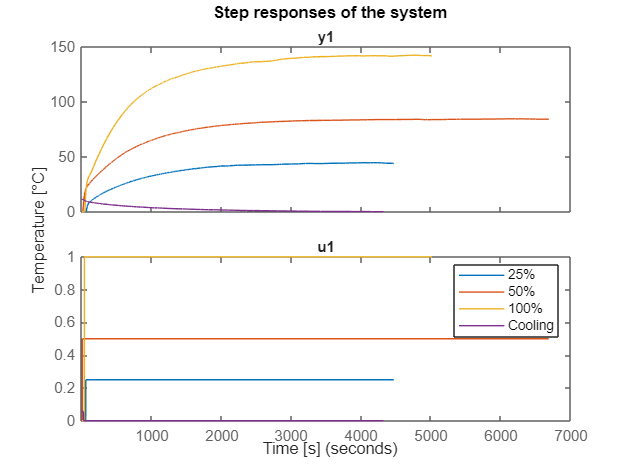

%%%%%%%%% tfest() funtion

%%%% unknown delay - in this case i'll let the software estimate the delay

%%%%%%%%% estimation data: data_100 (100% PWM duty cycle)

figure;

iodelay = NaN; %% unknown delay
model_tf1 = tfest(data_100,1,0,iodelay); %%%% 1st order transfer function
model_tf2 = tfest(data_100,2,1,iodelay); %%% 2nd order tf
model_tf3 = tfest(data_100,3,2,iodelay); %%% 3rd order tf

opt = compareOptions('InitialCondition','z'); %%%%%% initial conditions to zero

%%%% COMPARE fit
compare(data_100,model_tf1, model_tf2, model_tf3,opt)
title('100% PWM duty cycle')

compare(data_25,model_tf1,model_tf2, model_tf3,opt)
title('25% PWM duty cycle')
compare(data_50,model_tf1, model_tf2, model_tf3,opt)
title('50% PWM duty cycle')

**2.2 NLARX model with Wavelet and Sigmoid networks**

**Suitable regressor set for linear ARX model**

%%%%%  let's get hints what orders should be used in ARX model

%%% data est
data_est = merge(data_25,data_50, data_100);
V = arxstruc(data_est,data_50, struc(1:5, 1:5,1:5));
%%%% select best order by Akaike's information criterion (AIC)
nn = selstruc(V,'aic')


model_wavelet1 = nlarx(data_est, nn, idWaveletNetwork(8));
model_sigmoid1 = nlarx(data_est, nn, idSigmoidNetwork);


compare(data_100, model_sigmoid1,model_wavelet1)
compare(data_50, model_sigmoid1,model_wavelet1)
compare(data_25, model_sigmoid1,model_wavelet1)
compare(data_cooling, model_sigmoid1,model_wavelet1)

As a result, "wavelet" nlarx model is performing well. The fit is above 85% and although the validation through the cooling data wasn't quite accurate, it's the best model so far then it comes to the validation;

**2.3 NLARX model with Statistics and Machine Learning Toolbox**


data_est_light = merge(data_25_light,data_50_light,data_100_light,data_cooling_light);

%%% The following code was copied from the Matlab's website


nn =      5     5     5




 if exist('fitrgp','file' )   ==  2 
    Warn = warning('off','stats:lasso:MaxIterReached');
    mp1 = nlarx(data_est_light, nn, idGaussianProcess('Matern32'))

    % Create boosted ensemble of 300 regression trees
    En = idTreeEnsemble;
    En.EstimationOptions.FitMethod = 'lsboost-resampled';
    En.EstimationOptions.NumLearningCycles = 100;
    En.EstimationOptions.ResampleFraction = 1;
    mp2 = nlarx(data_est_light,nn, En)
    compare(data_100_light, mp1, mp2) % compare model fits to estimation data
    warning(Warn)
end

**2.4 NLARX model with DeepLearning Toolbox**


%%%% the following code was copied from Matlab's website

if exist('feedforwardnet','file')==2 % run only if Deep Learning Toolbox is available
    ff = feedforwardnet([5 20]);  % use a feed-forward network to map regressors to output
    ff.layers{2}.transferFcn = 'radbas';
    ff.trainParam.epochs = 40;
    ff.trainParam.showWindow = false;
    % Create a neural network mapping function that wraps the feed-forward network
    OutputFcn = idFeedforwardNetwork(ff);
    
    mn1 = nlarx(data_est_light,nn, OutputFcn); % estimate network parameters
    compare(data_25_light, mn1);  % tylko 1000 punktów zamiast całego zbioru
compare(data_100_light, mn1) % compare fit to estimation data%compare(data_100, mn1) % compare fit to estimation data
end



**2.5 Hammerstein-Wiener NLARX model**

%dds


mp1 =

Nonlinear ARX model with 1 output and 1 input
  Inputs: u1
  Outputs: y1

Regressors:
  Linear regressors in variables y1, u1
  List of all regressors

Output function: Gaussian process function using a Matern32 kernel
Sample time: 1 seconds

Status:                                                            
Estimated using NLARX on time domain data "data_est_light".        
Fit to estimation data: [99.8 99.86 99.9 99.38]% (prediction focus)
FPE: 0.0004732, MSE: [0.0004258 0.0003944 0.0008183 0.0002367]     




mp2 =

Nonlinear ARX model with 1 output and 1 input
  Inputs: u1
  Outputs: y1

Regressors:
  Linear regressors in variables y1, u1
  List of all regressors

Output function: Bagged Regression Tree Ensemble
Sample time: 1 seconds

Status:                                                              
Estimated using NLARX on time domain data "data_est_light".          
Fit to estimation data: [99.14 99.18 99.55 97.94]% (prediction focus)
MSE: [0.007511 0.01433 0.01709 0.002618]                             



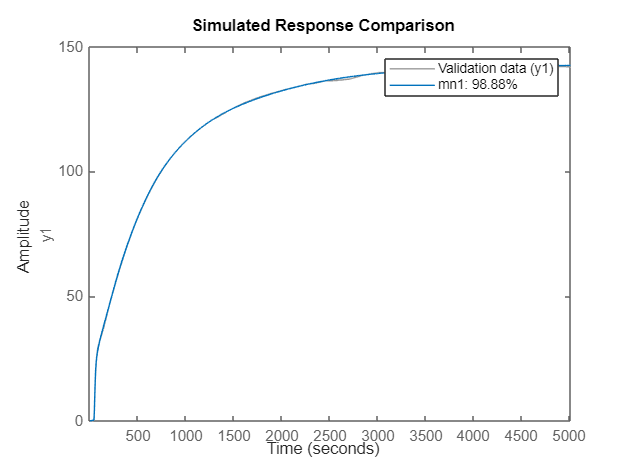

mhw1 = nlhw(data_est_light, nn, idPiecewiseLinear, idPiecewiseLinear);
mhw2 = nlhw(data_est_light, nn, idDeadZone, idSaturation);
mhw3 = nlhw(data_est_light, nn, idDeadZone, idUnitGain);

%%%%%%% the last hammerstein-wiener model
opt = nlhwOptions();
opt.SearchMethod = 'gna';
opt.SearchOptions.MaxIterations = 15;

mhw4 = nlhw(data_est_light, nn, idDeadZone, idSaturation, opt);
compare(data_50_light ,mhw1, mhw2,mhw3,mhw4)
compare(data_100_light ,mhw1, mhw2,mhw3,mhw4)

## **3.  System Identification Toolbox**

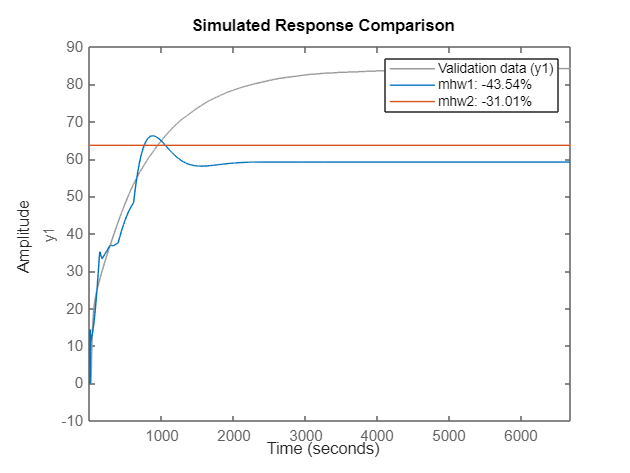

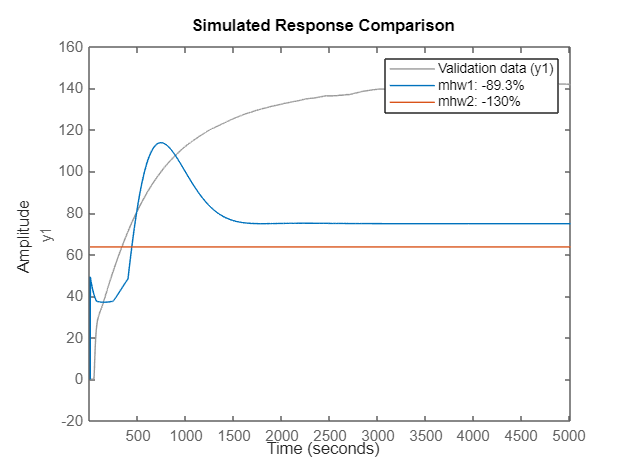

% systemIdentification   %%%% RUN SYSTEM IDENTIFICATION Toolbox

## **4. Compare results**